clc
clear

`Task 2`

I will now implement the Control variates.

N = 30;
I = 100;
h = 1/I;
I_2 = 50;
h2 = 1/(I_2);

M1 = 3000;
M2 = 3000;
param = 2.5;
x = linspace(0, 1, I+1);
x_h2 = linspace(0, 1, I_2+1);
x_half = zeros([I+1 1]);
x_half_h2 = zeros([I_2+1 1]);
for k=1:I
    x_half(k) = (x(k+1) + x(k))/2;
end

for k=1:I_2
    x_half_h2(k) = (x_h2(k+1) + x_h2(k))/2;
end




% TODO Generate RF samples a
tic
rng(2)
Y_main = normrnd(0, 1, [N M1]);
a_h2_main = zeros([M1 I_2+1]);

C_h2 = Matern_specialcases_only(x_half_h2, param);
[EVec_h2, EVal_h2] = eig(C_h2);
SV_h2 = zeros([I_2 1]);
EVec_h2 = flip(EVec_h2, 2);
for k=1:I_2
    SV_h2(k) = sqrt(EVal_h2(I_2+1-k, I_2+1-k));
end

for sample=1:M1
    % First part M1
    inner = zeros([I_2+1 N]);
    for k=1:N
        inner(:, k) = SV_h2(k)*Y_main(k, sample).*EVec_h2(:, k);
    end
    kappa = sum(inner, 2);
    a_h2_main(sample, :) = exp(kappa);
end

F_h2 = zeros([I_2+1 1]);
for i=1:I_2+1
    F_h2(i) = 4*pi^2*cos(2*pi*x_half_h2(i));
end
u_h2_main = zeros([M1 I_2+1]);
for sample=progress(1:M1)
    A_h2_main = zeros([I_2+1 I_2+1]);
    for i=2:I_2
       A_h2_main(i, i-1) = -a_h2_main(sample, i-1)/(h2^2);
       A_h2_main(i, i) = (a_h2_main(sample, i-1) + a_h2_main(sample, i+1))/(h2^2);
       A_h2_main(i, i+1) = -a_h2_main(sample, i+1)/(h2^2);
    end
    u_h2_main(sample, :) = A_h2_main(2:I_2, :)\F_h2(2:I_2);
end

Processing:  000%  |                                    | 0/3000it [00:00:00<Inf:NaN:NaN, Inf it/s]


QuantOfInt_h2_main = zeros([M1 1]);
for sample=1:M1
    QuantOfInt_h2_main(sample) = h2*sum(u_h2_main(sample, :));
end
toc

Elapsed time is 0.776069 seconds.


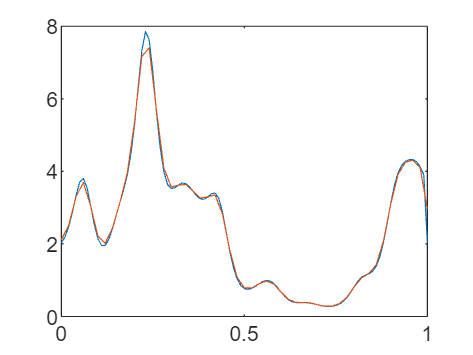


tic
rng(1)
x_hat = linspace(0, 1, N + 1);
Y = normrnd(0, 1, [N M2]);

a = zeros([M2 I+1]);
a_h2 = zeros([M2 I_2+1]);

% Covariance matrix construction for both h and 2h
C = Matern_specialcases_only(x_half, param);
[EVec, EVal] = eig(C);
SV = zeros([I 1]);
EVec = flip(EVec, 2);
for k=1:I
    SV(k) = sqrt(EVal(I+1-k, I+1-k));
end

for sample=1:M2
% Same for M2
    inner = zeros([I+1 N]);
    for k=1:N
        inner(:, k) = SV(k)*Y(k, sample).*EVec(:, k);
    end
    kappa = sum(inner, 2);
    a(sample, :) = exp(kappa);
    
    for i=1:I_2+1
        if i == 1
            a_h2(sample, i) = mean(a(sample, 1:2));
        elseif i == I/2+1
            a_h2(sample, i) = mean(a(sample, end-1:end));
        else
            a_h2(sample, i) =  mean(a(sample, 2*(i)-2:2*(i)));
        end
    end
    
end   

plot(x, a(1, :), x_h2, a_h2(1, :))


F = zeros([I+1 1]);
for i=1:I+1
    F(i) = 4*pi^2*cos(2*pi*x_half(i));
end

u_h = zeros([M2 I+1]);
u_h2 = zeros([M2 I_2+1]);

for sample=progress(1:M2)
    A = zeros([I+1 I+1]);
    A_h2 = zeros([I_2+1 I_2+1]);
    for i=2:I
       A(i, i-1) = -a(sample, i-1)/(h^2);
       A(i, i) = (a(sample, i-1) + a(sample, i+1))/(h^2);
       A(i, i+1) = -a(sample, i+1)/(h^2);
    end
    
    for i=2:I_2
       A_h2(i, i-1) = -a_h2(sample, i-1)/(h2^2);
       A_h2(i, i) = (a_h2(sample, i-1) + a_h2(sample, i+1))/(h2^2);
       A_h2(i, i+1) = -a_h2(sample, i+1)/(h2^2);
    end

    u_h(sample, :) = A(2:I, :)\F(2:I);
    u_h2(sample, :) = A_h2(2:I_2, :)\F_h2(2:I_2);
end

Processing:  000%  |                                    | 0/3000it [00:00:00<Inf:NaN:NaN, Inf it/s]



QuantOfInt = zeros([M2 1]);
QuantOfInt_h2 = zeros([M2 1]);
for sample=1:M2
    QuantOfInt(sample) = h*sum(u_h(sample, :));
    QuantOfInt_h2(sample) = h2*sum(u_h2(sample, :));
end
toc

Elapsed time is 2.101832 seconds.



% First the Estimators

MC_CV_1 = 1/M1*sum(QuantOfInt_h2_main) 

MC_CV_1 = -8.8583

MC_CV_2 = 1/M2*sum(QuantOfInt_h2 - QuantOfInt)

MC_CV_2 = 0.6855

MC_CV = MC_CV_1 + MC_CV_2

MC_CV = -8.1727

MC_crude = 1/M2*sum(QuantOfInt);

V_CV_1 = 1/M1*sum((QuantOfInt_h2_main - MC_CV_1).^2)

V_CV_1 = 633.3896

V_CV_2 = 1/M2*sum((QuantOfInt - QuantOfInt_h2 - MC_CV_2).^2)

V_CV_2 = 12.1719

V_CV = V_CV_1 + V_CV_2

V_CV = 645.5615

V_crude = 1/M2*sum((QuantOfInt - MC_crude).^2)

V_crude = 1.6803e+03



%{
for i=1:M2
    plot(x, u_h(i, :), x_h2, u_h2(i, :))
    hold on;
end

figure()
for i=1:M1
    plot(x_h2, u_h2_main(i, :))
    hold on;
end
%}

Above are the calculations for the Control variate approach. Now we only need the mean and variance using Monte Carlo.



%{
MC_est_CV = zeros([M1 M2]);
for i=1:M1
    for j=1:M2
        MC_est_CV(i, j) = 1/i*sum(QuantOfInt_h2_main(1:i)) + 1/j*sum(QuantOfInt(1:j) - QuantOfInt_h2(1:j));
        if i>1 & j>1
            MC_var_CV(i, j) = 1/(i-1)*sum(QuantOfInt_h2_main(1:i)) + 1/j*sum(QuantOfInt(1:j) - QuantOfInt_h2(1:j));
        end
    end
end 
%}

%{
for sample=progress(1:M2)
    ind = zeros([length(x) N]);
    ind_h2 = zeros([length(x_h2) N]);
    % Calculate for every node in the I mesh
    for l=1:length(x)
        % Check for every node in I mesh if its in [x^(k-1), x^(k)]
        for r=2:N+1
            if (x(l) >= x_hat(r-1) & x(l) <= x_hat(r))
                ind(l, r-1) = Y(r-1, sample);
            else
                ind(l, r-1) = 0;
            end
        end
    end

    for l=1:length(x_h2)
        % Check for every node in I mesh if its in [x^(k-1), x^(k)]
        for r=2:N+1
            if (x_h2(l) >= x_hat(r-1) & x_h2(l) <= x_hat(r))
                ind_h2(l, r-1) = Y(r-1, sample);
            else
                ind_h2(l, r-1) = 0;
            end
        end
    end

    stairs = crop(ind);
    stairs_h2 = crop(ind_h2);
    
            
    
    a(sample, :) = 1 + 0.5*stairs;
    a_h2(sample, :) = 1 + 0.5*stairs_h2;
end

for sample=progress(1:M2)
    ind_h2_main = zeros([length(x_h2) N]);
    for l=1:length(x_h2)
        % Check for every node in I mesh if its in [x^(k-1), x^(k)]
        for r=2:N+1
            if (x_h2(l) >= x_hat(r-1) & x_h2(l) <= x_hat(r))
                ind_h2_main(l, r-1) = Y_main(r-1, sample);
            else
                ind_h2_main(l, r-1) = 0;
            end
        end
    end
    stairs_h2_main = crop(ind_h2_main);
    a_h2_main(sample, :) = 1 + 0.5*stairs_h2_main;
end
%}